allPSTH.Aluminum=[];
allPSTH.Muted=[];
allPSTH.noObject=[];

rasterTemp = [];

data = IC_Galvo.E12_03_20_1722;

alumT = data.whisking_times.Aluminum(:,30000);
mutT = data.whisking_times.Muted(:,30000);
nonT = data.whisking_times.noObject(:,30000);

unitsFR = [];
units_g = data.clusterSpikes.good.times;
units_m = data.clusterSpikes.mua.times;
k = size(units_g,1);
for i = 1:size(units_g,1)
        unitsFR(i) = length(nonzeros(units_g(i,:)))/(max(units_g(i,:)/30000));
end
for ii = 1:size(units_m,1)
        unitsFR(ii+k) = length(nonzeros(units_m(ii,:)))/(max(units_m(ii,:)/30000));
end

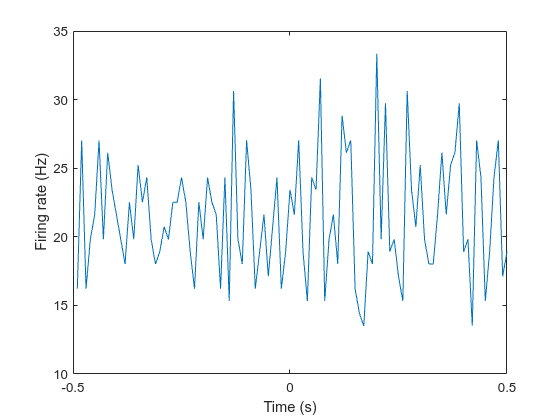

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


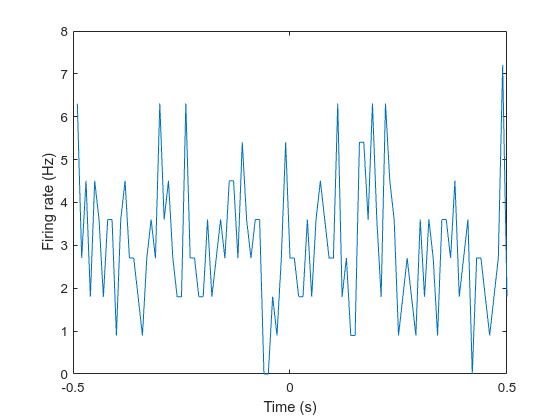

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


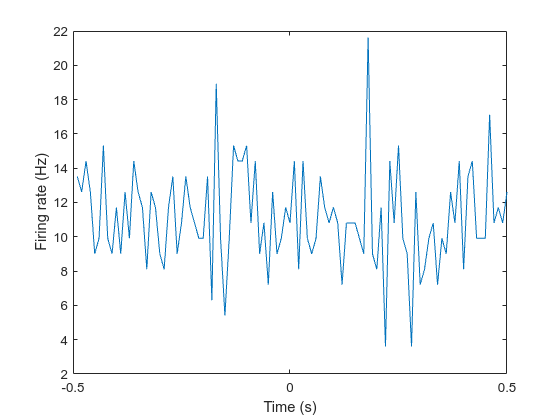

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


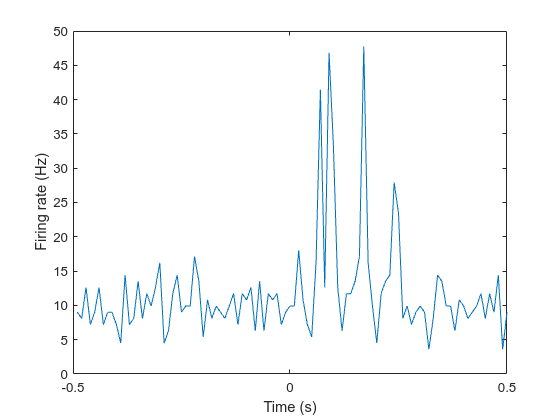

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


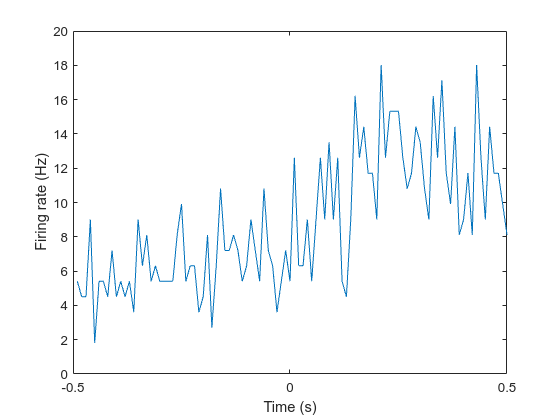

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


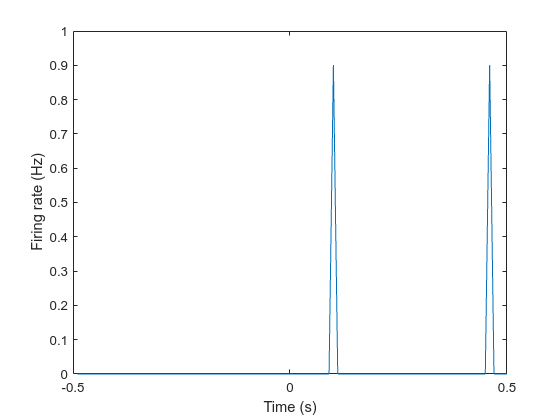

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


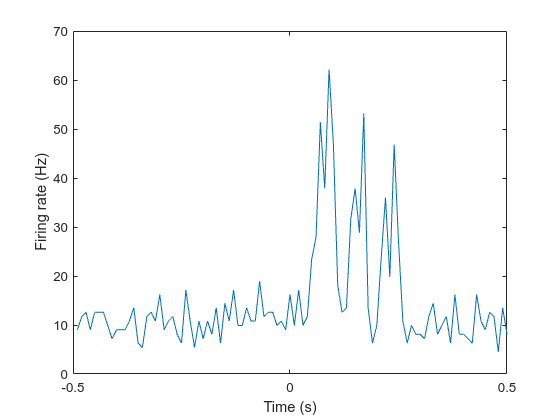

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


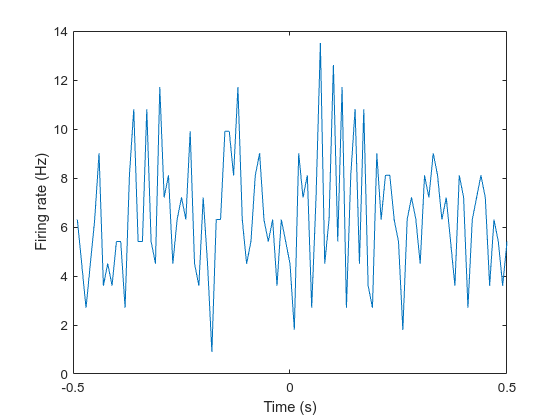

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


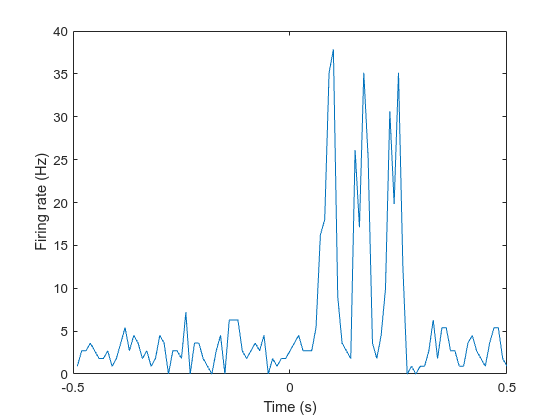

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


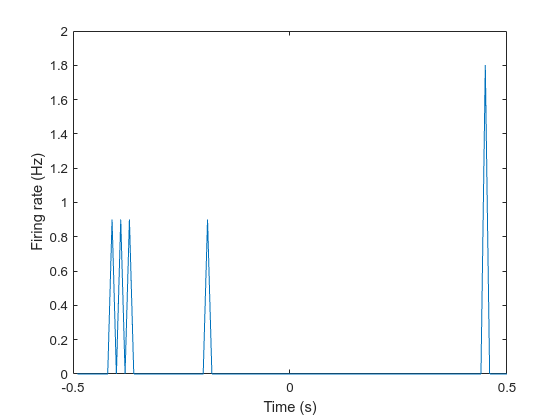

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


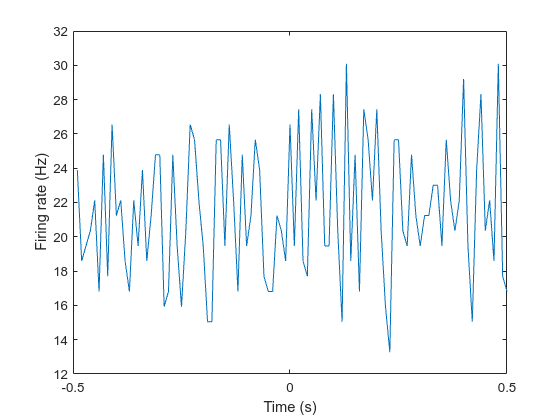

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


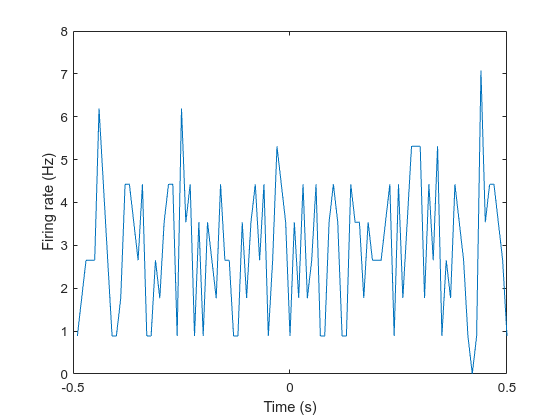

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


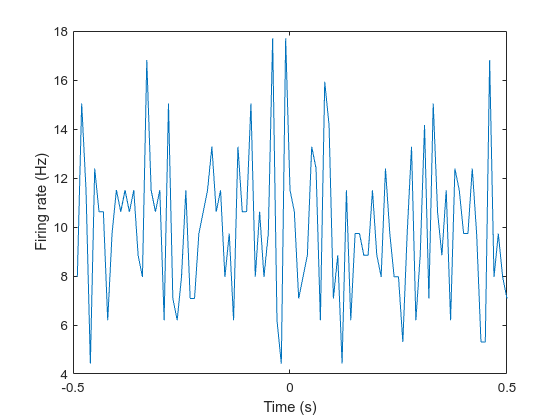

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


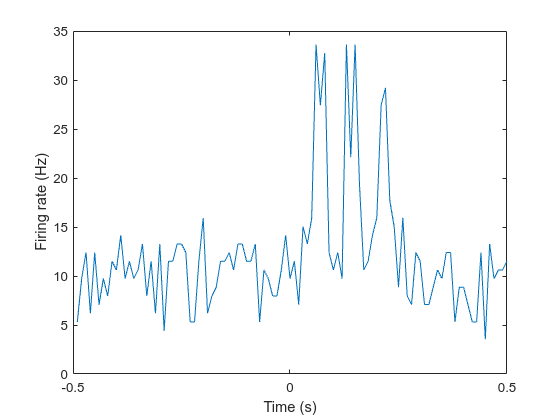

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


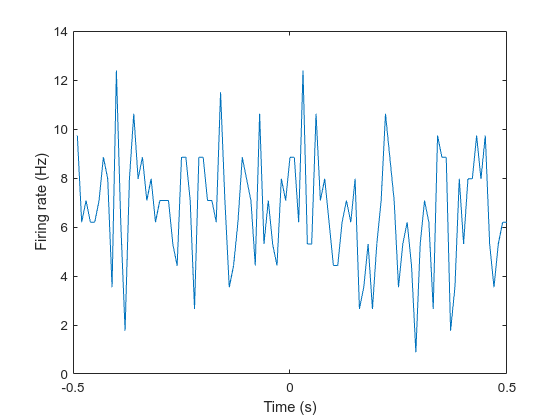

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


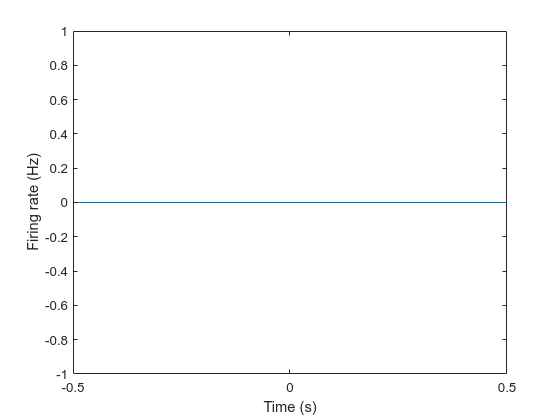

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


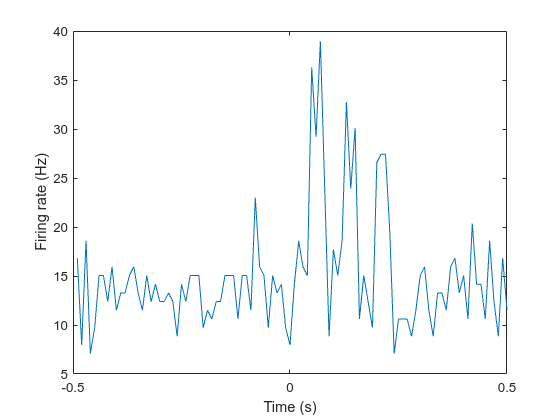

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


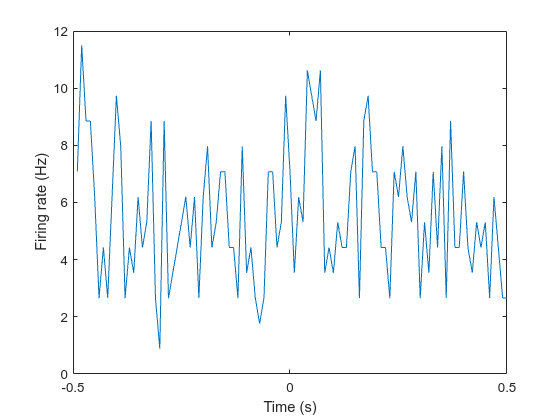

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


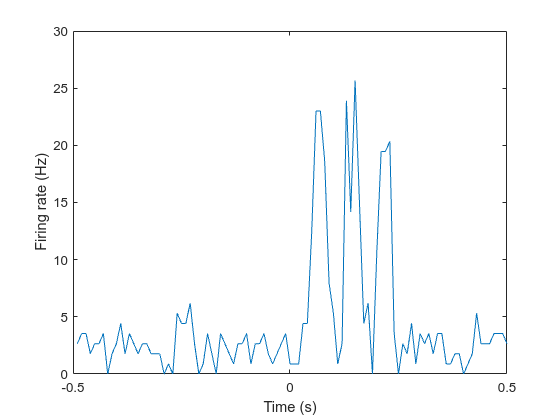

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


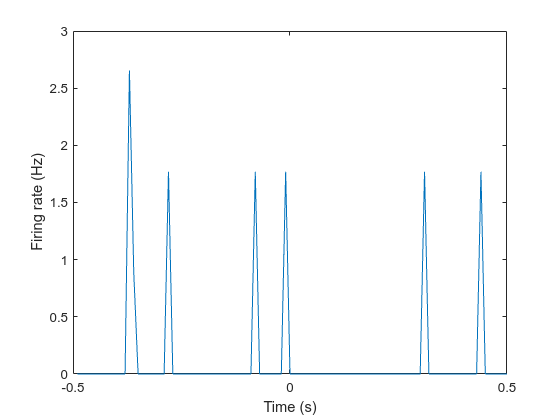

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


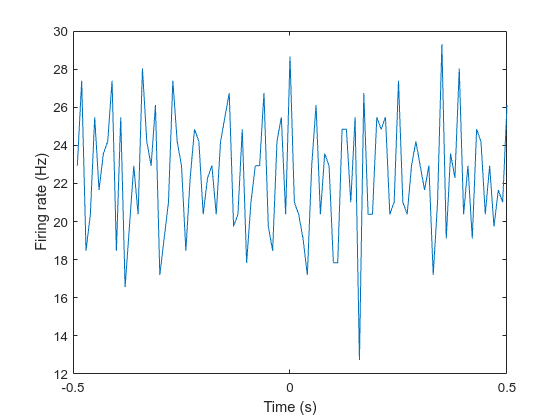

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


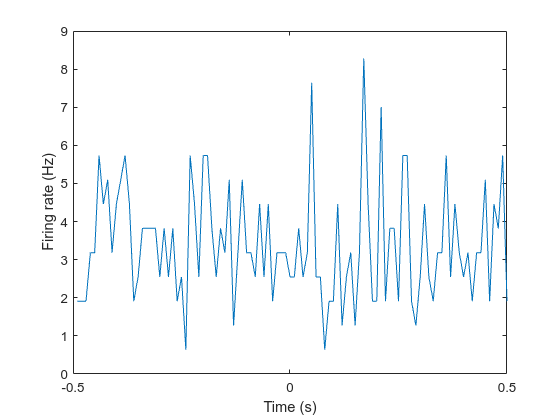

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


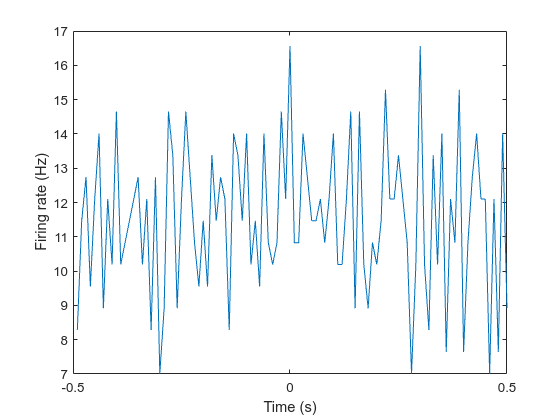

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


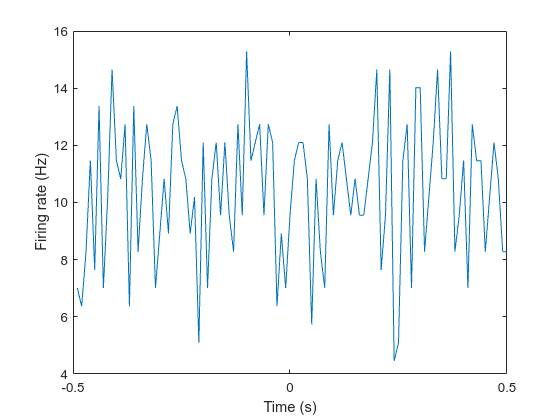

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


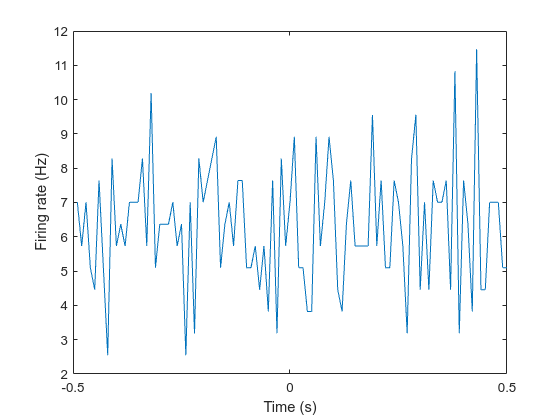

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


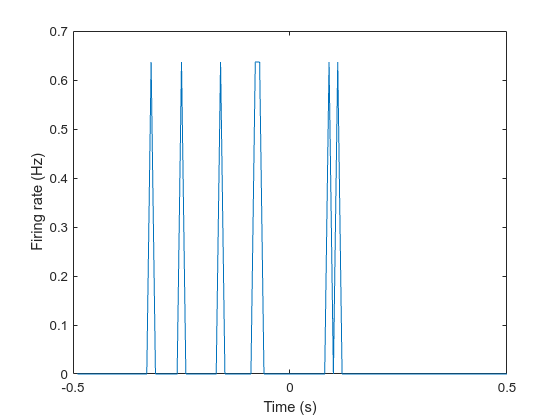

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


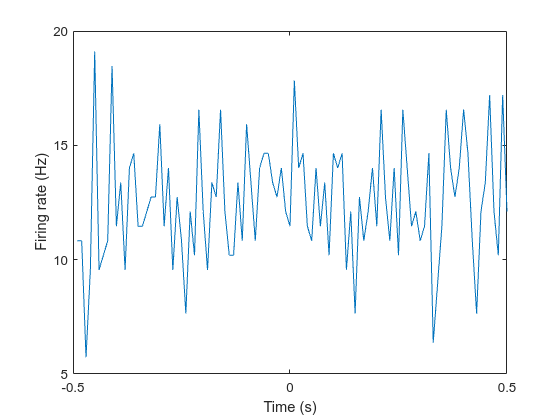

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


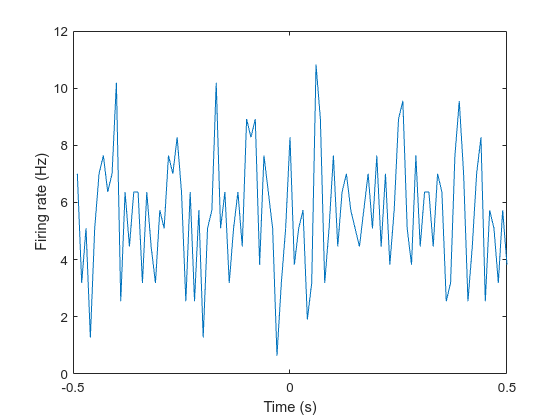

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


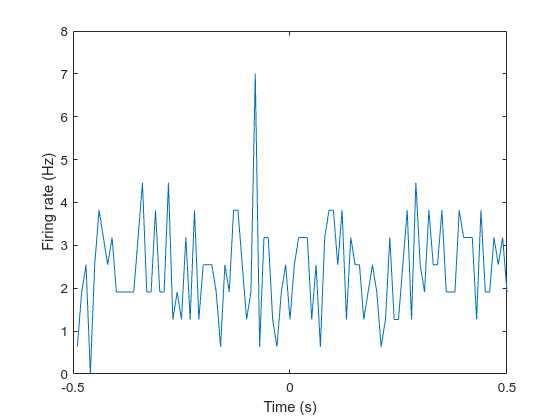

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


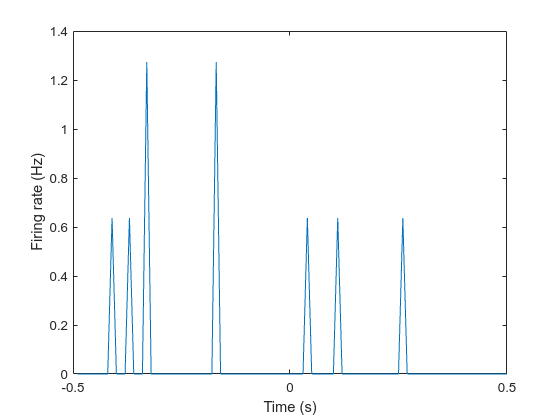

allPSTH = struct with fields:
    Aluminum: [10×100 double]
       Muted: [10×100 double]
    noObject: [10×100 double]


conditions = {'Aluminum','Muted','noObject'};
for kk = 1:3
    for i = 1:size(units_g,1)
        allPSTH.(conditions{kk})(i,:) = psth(createRaster(data.whisking_times.(conditions{kk})(:,30000),units_g(i,:),1),10)./unitsFR(i)
    end
    for ii = 1:size(units_m,1)
        allPSTH.(conditions{kk})(ii+k,:) = psth(createRaster(data.whisking_times.(conditions{kk})(:,30000),units_m(ii,:),1),10)./unitsFR(ii+k)
    end
end

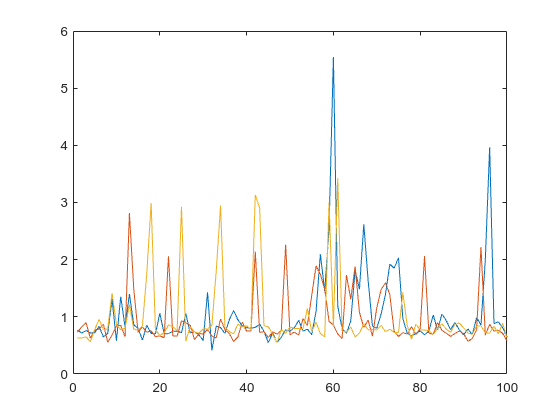

figure;plot(mean(allPSTH.Aluminum))
hold on;plot(mean(allPSTH.Muted))
plot(mean(allPSTH.noObject))